# Usage of AAKR for RUL prediction

training_state=[8.99,17.75,32.17;
    4.34,19.42,33.12;
    8.00,16.15,35.04;
    5.91,18.47,29.59];
traning_RUL=[5.76;6.25;6.82;5.85];
obs_state = [4.15,14.53,28.96]

obs_state =     4.1500   14.5300   28.9600


Frist, we normalize the data

mean_state = mean(training_state);
std_state = std(training_state);
traning_state_nor = (training_state-mean_state)./std_state;
obs_state_nor = (obs_state-mean_state)./std_state;

Then, we then calculate the distance and the weight.

h = 2;
d = (traning_state_nor-obs_state_nor).^2*[1;1;1];
w = 1./sqrt(2*pi)./h.*exp(-d.^2./2./h.^2);

After that, we canculate the AAKR value

nc_state = (w.')*training_state/sum(w)

nc_state =     5.9108   18.4691   29.5920


RUL_pre = (w.')*traning_RUL/sum(w)

RUL_pre = 5.8503

Finally we plot it.

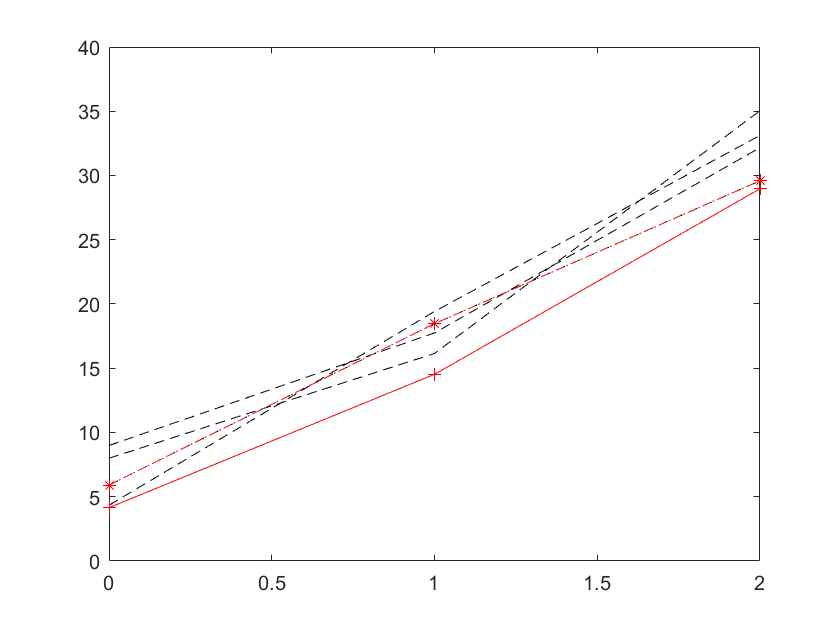

plot([0;1;2],training_state,'k--')
hold on;
plot([0;1;2],nc_state,'r-.*')
plot([0;1;2],obs_state,'r-+')